clc;clear;

num = 0;cnt = 0;index = 1;
cnt1 = 0;cnt2 = 0;
for i = 1:5856
    num = num + PekingTemp_6per(i);
    cnt = cnt + 1;
    if cnt == 4
        cnt = 0;
        PekingTemp(index) = num/4;
        num = 0;
        cnt1 = cnt1 + 1;
        index = index + 1;
    end
end

for i = 1:37288
    num = num + PekingTemp_3per(i);
    cnt = cnt + 1;
    if cnt == 8
        cnt = 0;
        PekingTemp(index) = num/8;
        num = 0;
        cnt2 = cnt2 + 1;
        index = index + 1;
    end
end
index = index - 1;

% plot(res)
tanh(10000000)

ans = 1

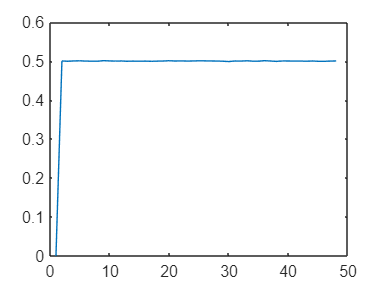

plot(res)

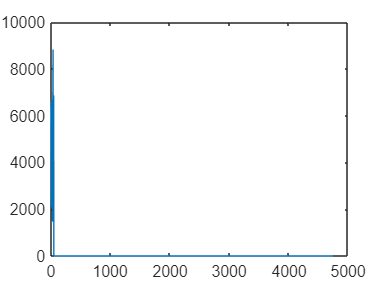

plot(u)

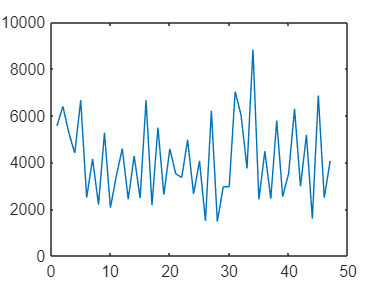

xxxx = 1:4745;
for iii = 1:4745
    Fourier_8__(iii) = Fourier_8(iii);
end
for iii =1:47
    u_re(iii) = u(iii);
end
% plot(xxxx,y,xxxx,Fourier_8__)
plot(u_re)

mean(u_re)

ans = 4.1061e+03



hold off

dataOfTemp = trainYearsTemp;
%建立符号变量a(发展系数)和b(灰作用量)
syms a b;
c = [a b]';
increase = 4;
inc = increase;

%原始数列 A
%A = [174, 179, 183, 189, 207, 234, 220.5, 256, 270, 285];
A = dataOfTemp';
n = length(A);

%对原始数列 A 做累加得到数列 B
B = cumsum(A);

C = 0;
%对数列 B 做紧邻均值生成
for i = 2:n
    C(i) = (B(i) + B(i - 1))/2; 
end
C(1) = [];

%构造数据矩阵 
B = [-C;ones(1,n-1)];
Y = A; Y(1) = []; 
%Y = Y';


%使用最小二乘法计算参数 a(发展系数)和b(灰作用量)
c = inv(B*B')*B*Y;
c = c';
a = c(1); b = c(2);

%预测后续数据
F = []; F(1) = A(1);
for i = 2:(n+inc)
    F(i) = (A(1)-b/a)/exp(a*(i-1))+ b/a;
end

%对数列 F 累减还原,得到预测出的数据
G = []; G(1) = A(1);
for i = 2:(n+inc)
    G(i) = F(i) - F(i-1); %得到预测出来的数据
end

disp('预测数据为：');
G

%模型检验

H = G(1:inc);
%计算残差序列
epsilon = A - H;

%法一：相对残差Q检验
%计算相对误差序列
delta = abs(epsilon./A);
%计算相对误差Q
disp('相对残差Q检验：')
Q = mean(delta)

%法二：方差比C检验
disp('方差比C检验：')
C = std(epsilon, 1)/std(A, 1)

%法三：小误差概率P检验
S1 = std(A, 1);
tmp = find(abs(epsilon - mean(epsilon))< 0.6745 * S1);
disp('小误差概率P检验：')
P = length(tmp)/n


%绘制曲线图
% t1 = 2006:(1/365):(2018+364/365)
% t2 = 2006:(1/365.25):(2022+360/365);

t1 = 2006:2018;
t2 = 2006:2022;

plot(t1, A,'.'); 
hold on;
plot(t2, G, 'g-');
xlabel('年份/年'); ylabel('温度/℃');
legend('实际气温','预测气温');
title('基于GM的北京气温曲线');
grid on;

for i = 14:17
    YPred(i-13) = G(i-13);
    YReal(i-13) = each_year_latter_ave(i-13);
end
mae = mean(abs(YReal - YPred))
sse = sum((YPred - YReal).^2)
rmse = sqrt(mean((YPred-YReal).^2))
mape = mean(abs((YReal - YPred)./YReal))*100  

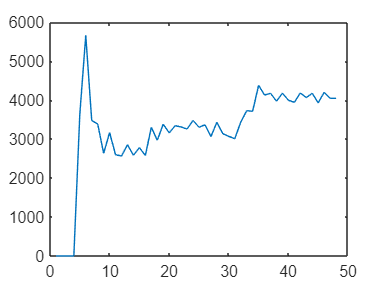

plot(res)

% for i = 1 : 3159
%     YPred(i) = G(i);
%     Obverval(i) = A(i);
%     YReal(i) = A(i);
% end
% 
% for i = 1 : 263
%     for j = 1 : 12
%         incr = (i-1)*12+j;
%         temp = temp + G(incr + 3);
%     end
%     GMlinear(i) = temp/12;
%     temp = 0;
% end
% 
% mae = mean(abs(YReal - YPred))
% sse = sum((YPred - Obverval).^2)
% rmse = sqrt(mean((YPred-Obverval).^2))
% meap = mean(abs((Obverval - YPred)./Obverval))*100
% 
% cnt = 0; temp = 0;
% for i = 1 : 263
%     for j = 1 : 12
%         incr = (i-1)*12+j;
%         temp = temp + A(incr + 3);
%     end
%     aveOfTemp(i) = temp/12;
%     temp = 0;
% end
% 
% for i = 1: 24
%     for j = 1 : 12
%         incr = (i-1)*12+j;
%         temp = temp + G(incr + 3159);
%     end
%     aveOfGMforecast(i) = temp/12;
%     temp = 0;
% end
% 
% 
